clear; clc;
format long;
data = csvread('data.csv', 1, 0);

hold on;
scatter(data(:,1), data(:,2));
label0 = 'csv-data';
hold off;

% result fuction with all points
fx_result = @(x) -0.2805016493803706*x^2 + 2.8400814288686433*x + 2.140542066628967;
% result function with only two points
fx_result_two = @(x) -0.5333333333333338*x + 9.633333333333336;
% result function with only two points
fx_result_two_two = @(x) 6.394884621840902E-14*x^2 + 0.1444444444444443*x + 2.727777777777778;
% result function with only three points
fx_result_three = @(x) -0.29599999999999965*x^2 + 3.0999999999999965*x + 1.7000000000000028;

hold on;
plot1 = fplot(fx_result, [0, 10], 'LineWidth',2); 

label1 = 'calculated with least squares';
hold off;

hold on;
plot2 = fplot(fx_result_two, [0, 10], 'LineWidth',2); 
label2 = 'calculated with least squares (two points)(1)';
hold off;

hold on;
plot3 = fplot(fx_result_two_two, [0, 10], 'LineWidth',2); 

label3 = 'calculated with least squares (two points)(2)';
hold off;

hold on;
plot4 = fplot(fx_result_three, [0, 10], 'LineWidth',2); 

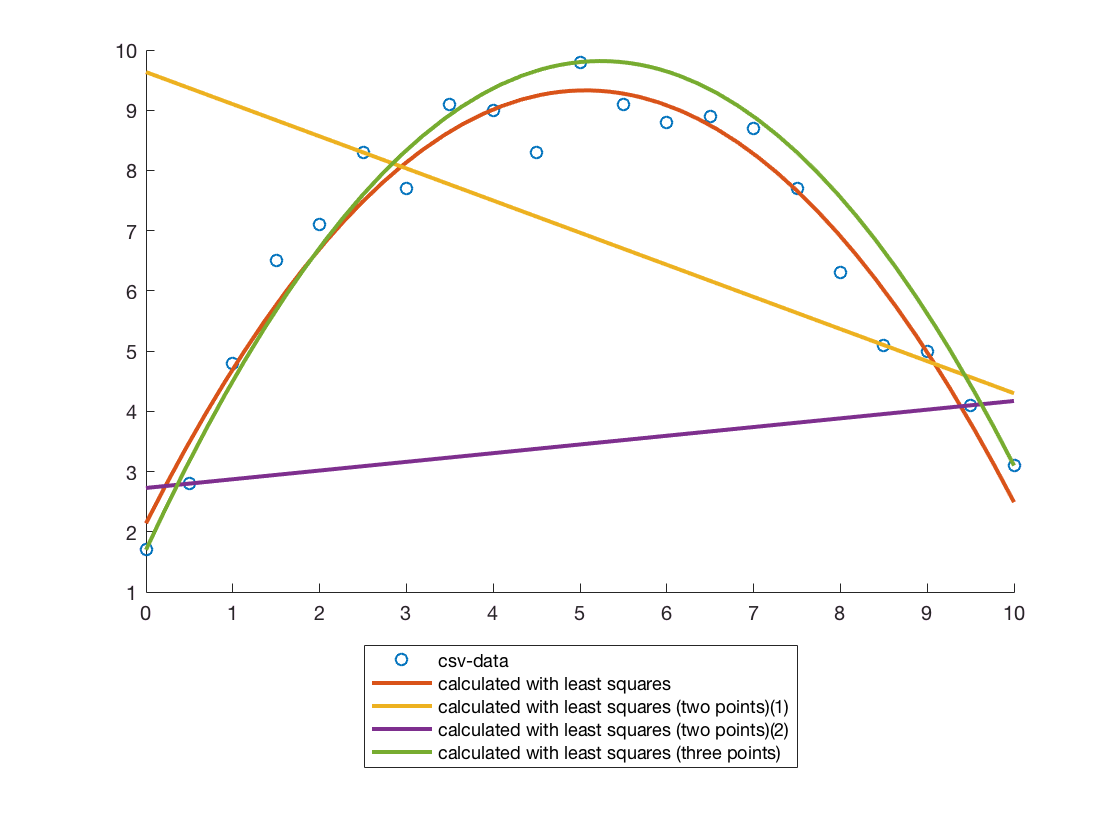

label4 = 'calculated with least squares (three points)';
hold off;

title('Least Square Example');
legend(label0, label1, label2, label3, label4,'Location','southoutside');